f = @(phi) tan(polyval([1 2 2], phi));
integral(f,0,pi/4)

ans = -0.1803

p = @(phi) polyval([1 2 2], phi);
integral(@(phi) tan(p(phi)), 0, pi/4)

ans = -0.1803

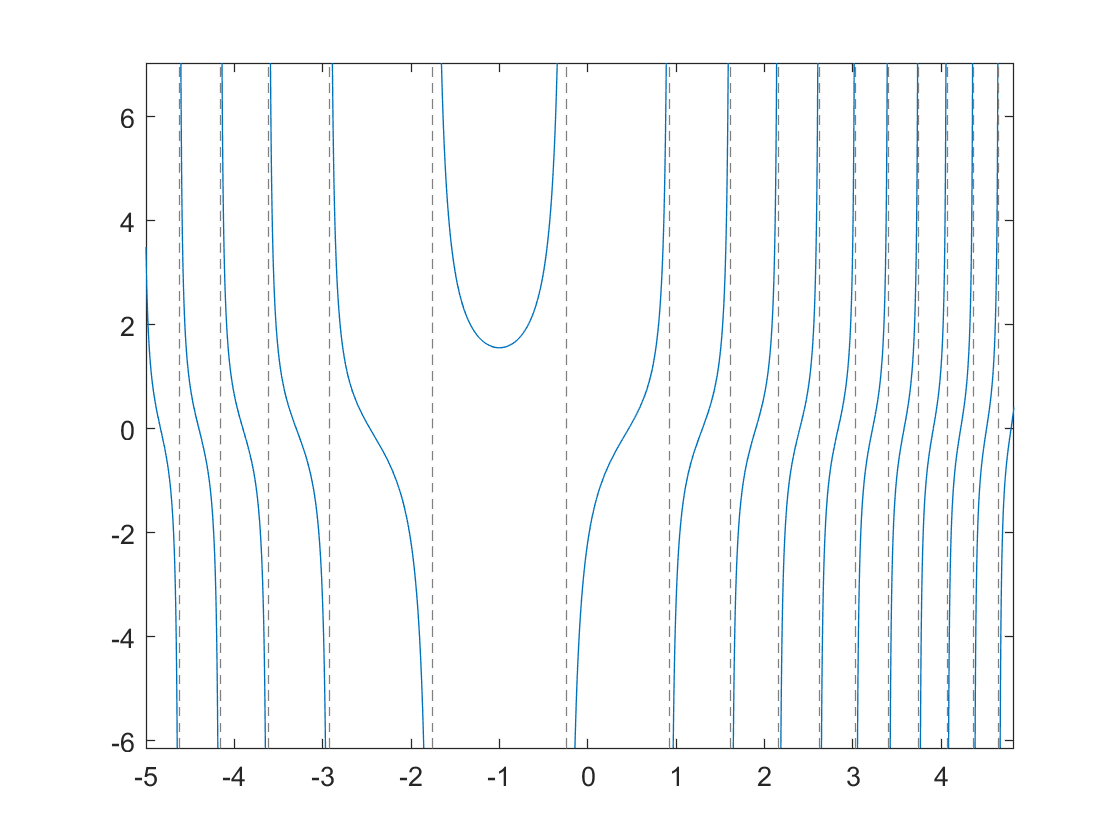

fplot(f);

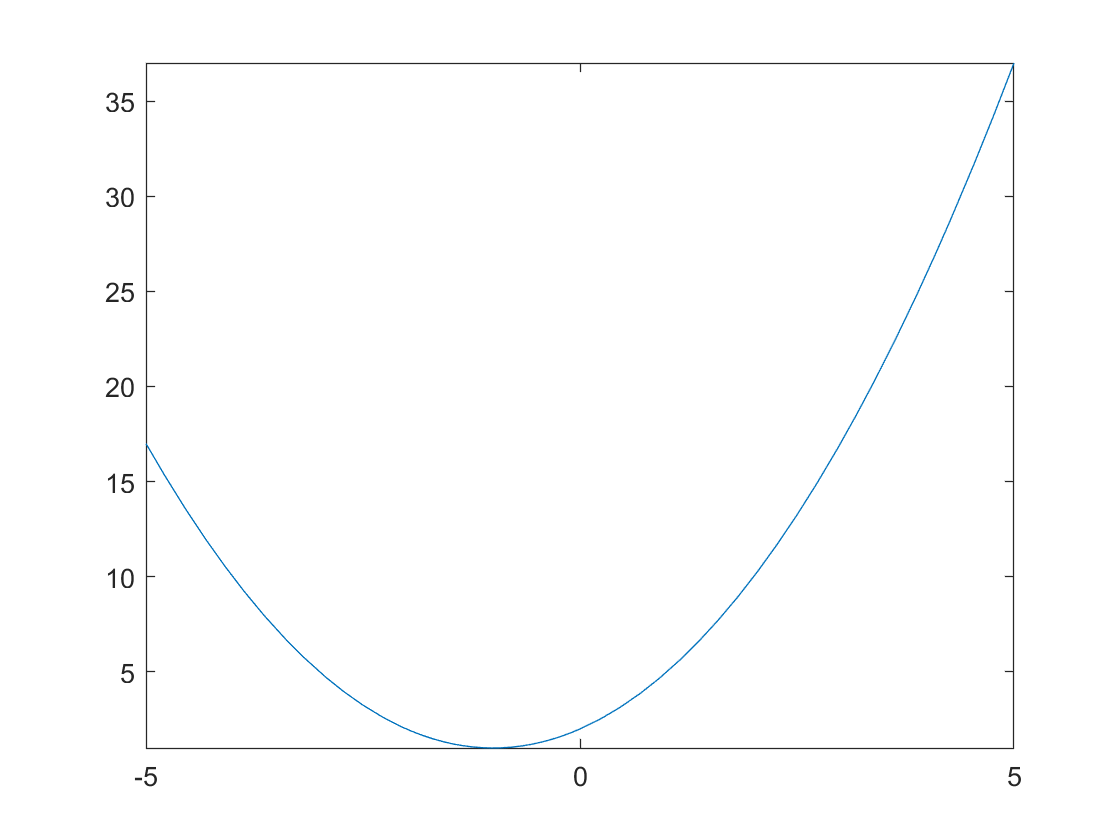

fplot(p);

% Remember to use dot operator for elementwise vector functions

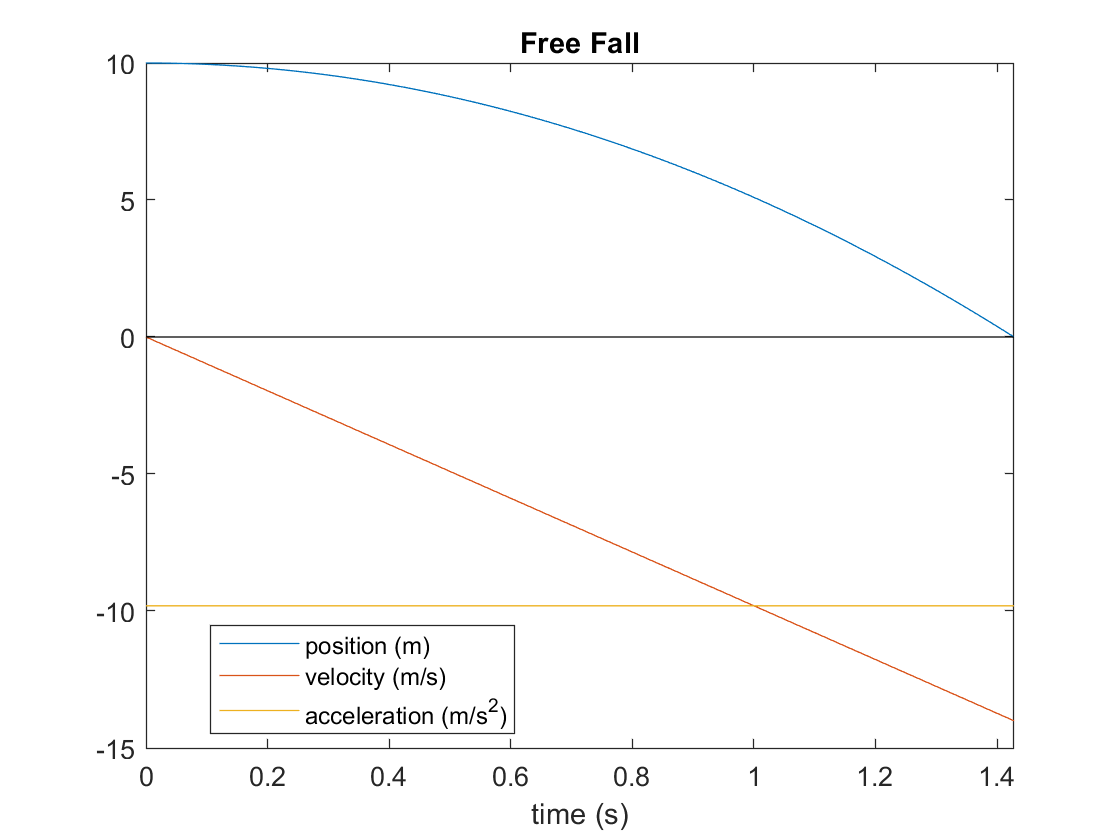

% Free Fall in a Vacuum:
% a(t) = -g
% v(t) = v(0) - g * t
% x(t) = h + v(0) * t - 0.5 * g * t.^2

% Trajectory of Body
g = 9.81;
h = 10;
v0 = 0;

% Time Calculation
T = v0/g + sqrt((v0/g)^2 + 2*h/g);
t = linspace(0,T,100);

% Functions
a = @(u) repmat(-g,size(u));
v = @(u) v0 - g*u;
x = @(u) h + v0*u - 0.5*g*u.^2;

% Plot Setup
hp = plot(t, [x(t); v(t); a(t)]);
xlim([0 T]);
line(xlim,[0 0],'Color','k');
legend(hp,'position (m)','velocity (m/s)','acceleration (m/s^2)','location','best');
title('Free Fall');
xlabel('time (s)');

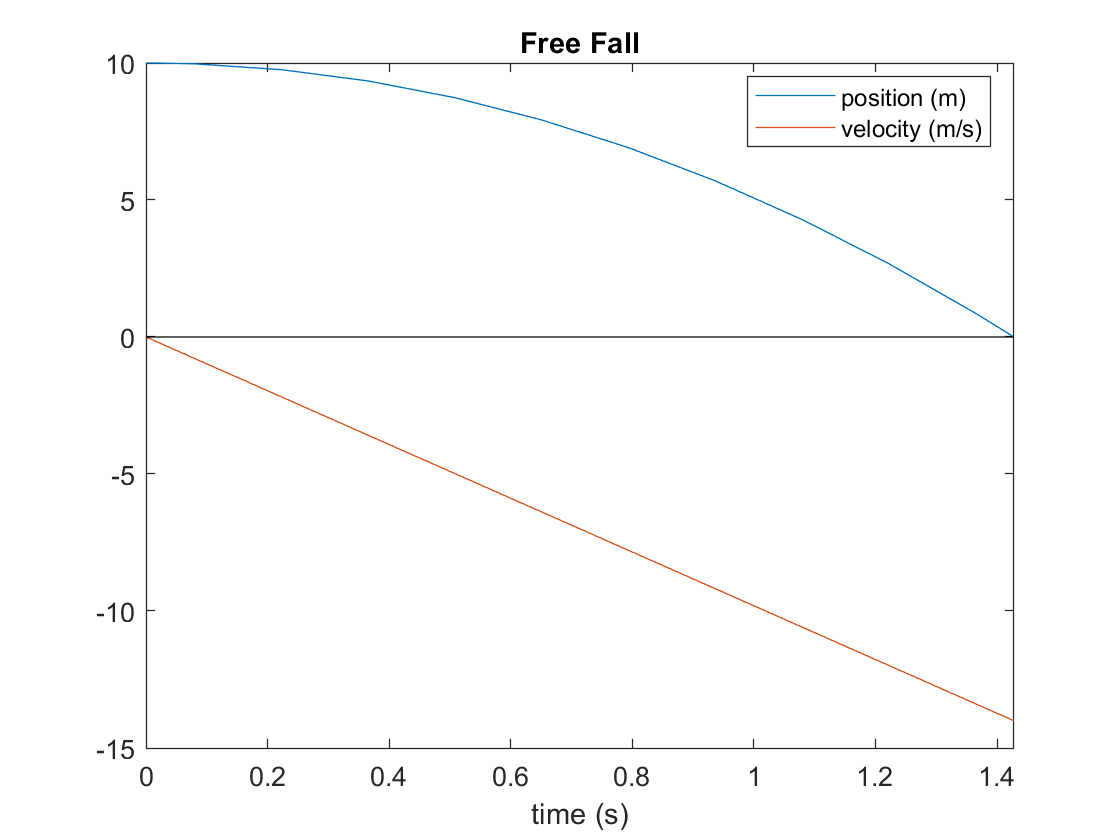

% Use of ODE45 inside a function
freefallode;

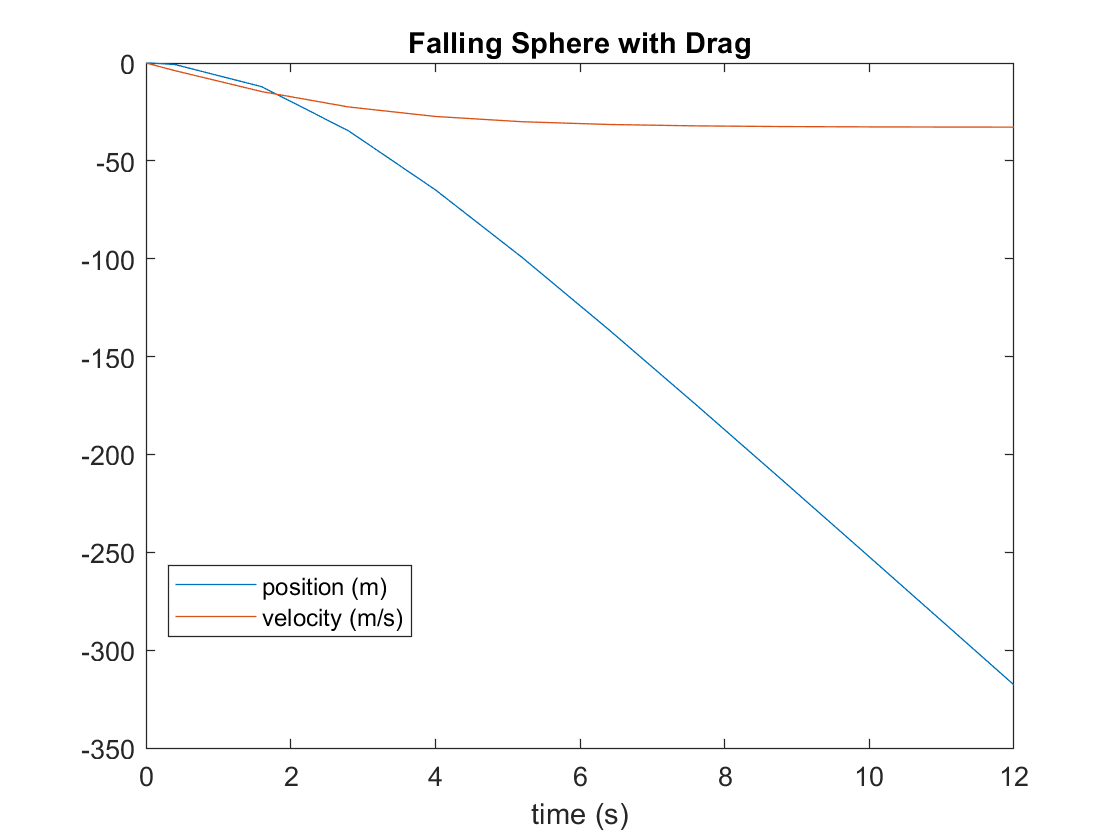

% Adding Air Drag
% Speed = sqrt(2 * g * h)
% Air Drag = 0.5 * rho * A * D * v
% Terminal Velocity = sqrt(2 * m * g / rho * A * D)
drag;

% Modeling DC Motor
% J * v'' = K * I - eta * v' - tau
% L * I' + R * I = V  - K * v'